# Parameters for 3D pendulum simulation            

## Introducing the 3D pendulum:

Our 3D pendulum looks like this:

##   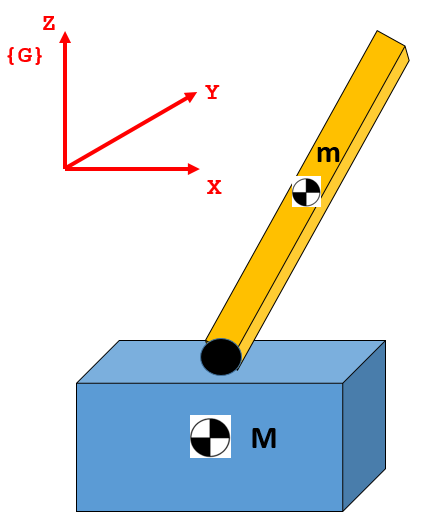     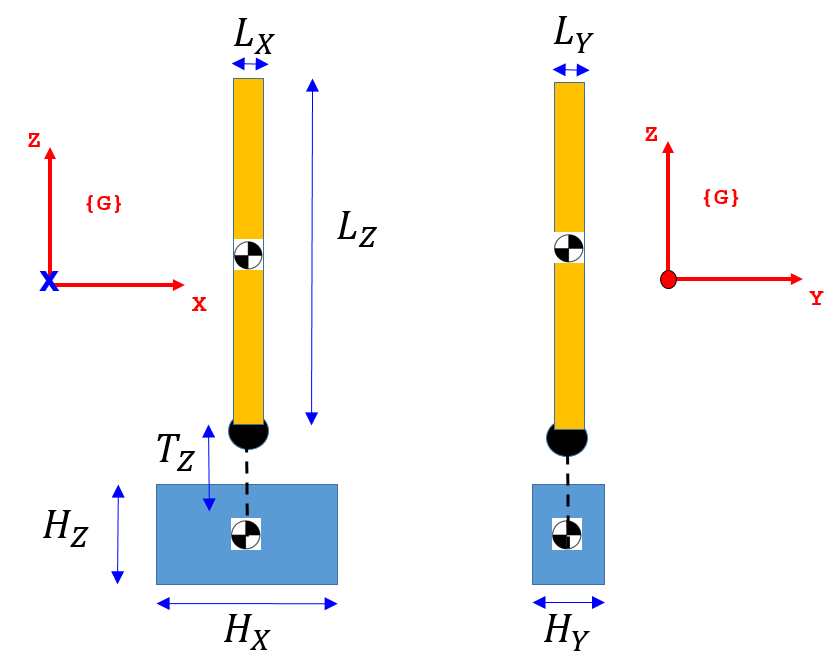

- The pendulum is attached to the base cart via a spherical joint.  

- The sperical joint permits the pendulum to yaw, pitch and roll.  

- The base cart may translate in the inertial X,Y, and Z directions.

- We will be applying forces to the Base cart only

- We will represent the base cart as a point mass.

## Defining the some model parameters:

syms  m_pend  M_cart g
syms  Tv_Z  Lx  Ly  Lz

M_cart = 0.9272;  % kg
m_pend = 0.25;    % kg

Hx     = 0.15; % m
Hy     = 0.1;  % m
Hz     = 0.1;  % m

Tv_Z   = Hz/2 + 0.05; % m

Lz     = 0.5;  % m
Lx     = 0.02; % m
Ly     = 0.02; % m
g      = 9.80665; % m/sec^2

## The system INITIAL Conditions:

define the state vector to be:  $q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ} \}$ - NOTE it ***must be this*** because of the equation derivation

          % rad                 m 
q0      = [ 0, 0, 0,     0,0,0];

          % rad/sec     m/sec
q0_dot  = [0,0,0,     0,0,0];

For convenience (for Simscape model) define the initial pendulum angles in degrees:

q0_ang_deg     = q0(1:3)     * 180/pi;  % deg
q0_dot_and_deg = q0_dot(1:3) * 180/pi;  % deg/sec

**Load Measurement BUS object:**

This is needed for the Simulink component model:

bh_create_3d_pend_SL_MEAS_BUS